%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Fix missing data in dataset, remove column 19 since is the duplicate of the 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"knn");
%split type of day in 3 boolean column
%[sun=0, rain=1, snow=2]
type_of_day = dummyvar(short_matrix_no_id(:, 16) + 1);
short_matrix_no_id(:,16) = [];
%concat type of day at the end of the dataset
short_matrix_no_id = [short_matrix_no_id, type_of_day];

%NORMALIZE DATA
short_matrix_no_id(:,[2:5,9:14,17]) = normalize(short_matrix_no_id(:,[2:5,9:14,17]), 'range', [0, 1]);
%short_matrix_no_id(:,[2:4]) = normalize(short_matrix_no_id(:,[2:4]), 'range', [0, 1]);
%short_matrix_no_id(:,[5,9:15,18]) = zscore(short_matrix_no_id(:,[5,9:15,18]));

%BUS LINE connected features matrix
bus_line = short_matrix_no_id(:,[1, 2:6, 8:9, 15, 16, 18:20]);

%Vehicle ID connected features matrix
vehicle_id = short_matrix_no_id(:,[1, 6:8, 11:15, 17]);

%driver id connected features matrix
driver_id = short_matrix_no_id(:, [1, 6, 8, 15]);


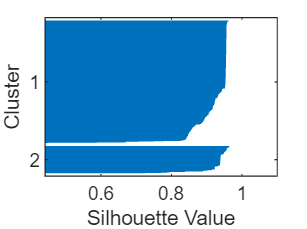

ans = 0.9256

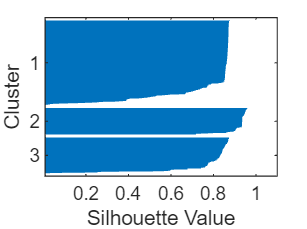

ans = 0.8073

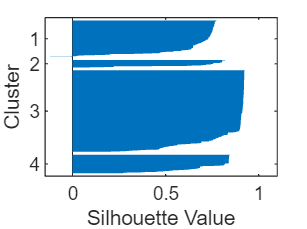

ans = 0.7706

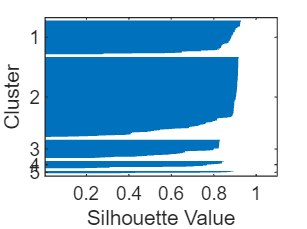

ans = 0.8126

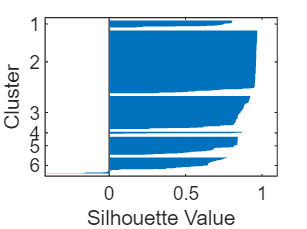

ans = 0.8079

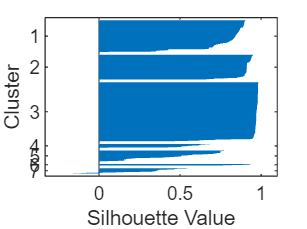

ans = 0.8335

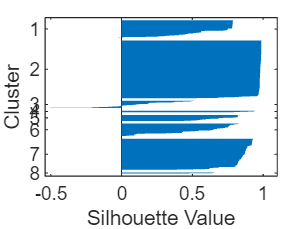

ans = 0.7952

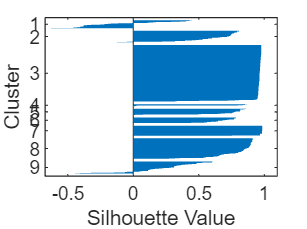

ans = 0.7452

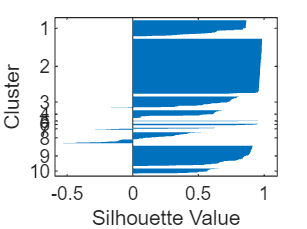

ans = 0.7460

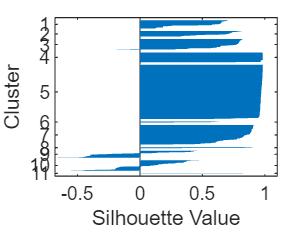

ans = 0.7279

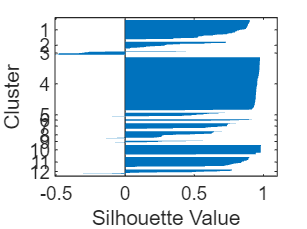

ans = 0.7546


%Starting calculation for number of clusters 
unique_driver = unique(short_matrix_no_id(:,8),"rows"); %229 istances
unique_vehicle = unique(short_matrix_no_id(:,6),"rows"); %105 istances
unique_line = unique(short_matrix_no_id(:,1),"rows"); % 87 istances

% Range of number of clusters
k_values = 2:12;

% Initialize array to store percentage variance for each matrix
variance_pct_driver = zeros(size(k_values));
variance_pct_vehicle = zeros(size(k_values));
variance_pct_busline = zeros(size(k_values));
mean_silhouette_scores = [];
% Perform k-means clustering for each number of clusters on driver_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on driver_id
    [idx_driver, centroids, sumd] = kmeans(driver_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_driver(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(driver_id,idx_driver);
    silhouette(driver_id,idx_driver);

    mean(sil_scores)
    
end

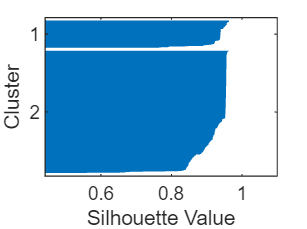

ans = 0.9256

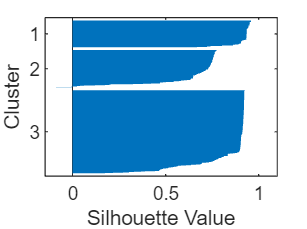

ans = 0.8097

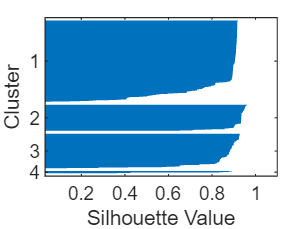

ans = 0.8515

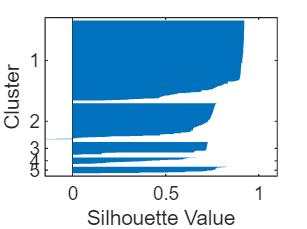

ans = 0.7465

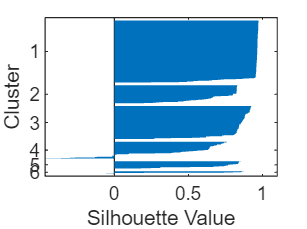

ans = 0.8047

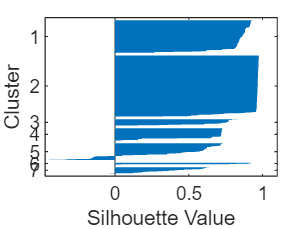

ans = 0.7777

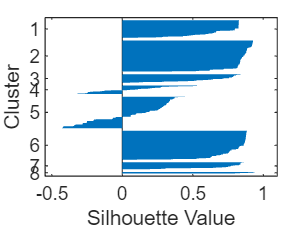

ans = 0.5630

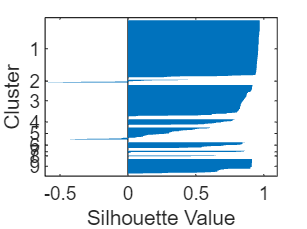

ans = 0.7843

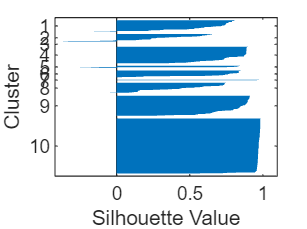

ans = 0.7861

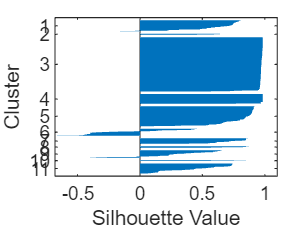

ans = 0.7547

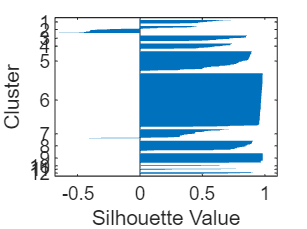

ans = 0.7713


% Perform k-means clustering for each number of clusters on vehicle_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on vehicle_id
    [idx_vehicle, centroids, sumd] = kmeans(vehicle_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_vehicle(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(vehicle_id,idx_vehicle);
    silhouette(vehicle_id,idx_vehicle);
    mean(sil_scores)
    
end

ans = 0.9256

ans = 0.8073

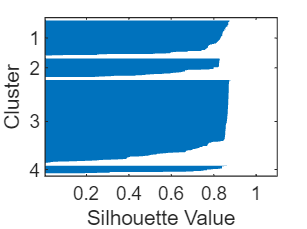

ans = 0.7680

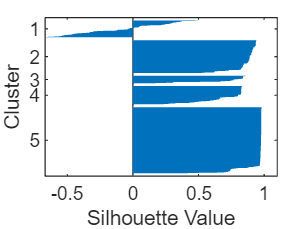

ans = 0.7636

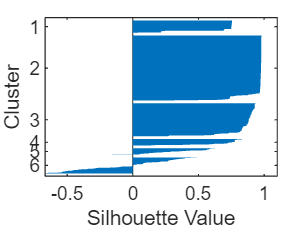

ans = 0.7430

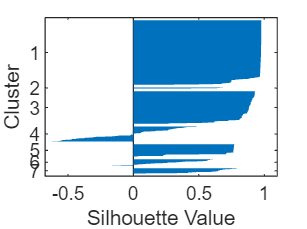

ans = 0.7446

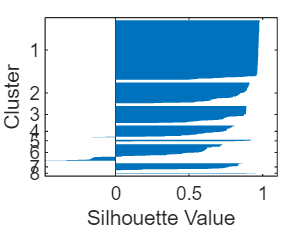

ans = 0.7919

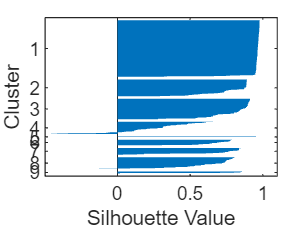

ans = 0.7832

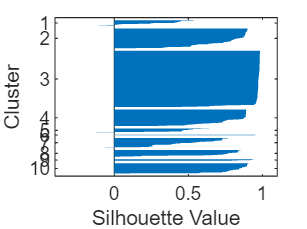

ans = 0.8023

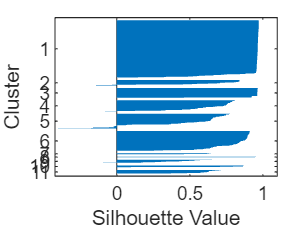

ans = 0.7903

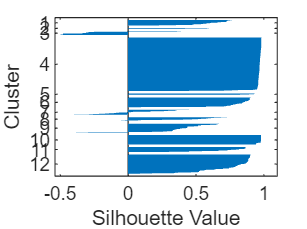

ans = 0.7622


% Perform k-means clustering for each number of clusters on bus_line
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on bus_line
    [idx_line,centroids, sumd] = kmeans(bus_line, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_busline(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(bus_line,idx_line);
    silhouette(bus_line,idx_line);
    mean(sil_scores)
end

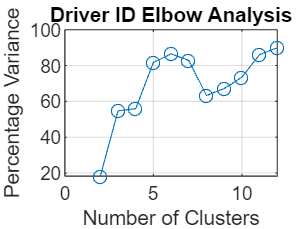

% Plot elbow curves for each matrix separately
%Elbow curve driver id cluster
figure;
plot(k_values, variance_pct_driver, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Driver ID Elbow Analysis');
grid on;

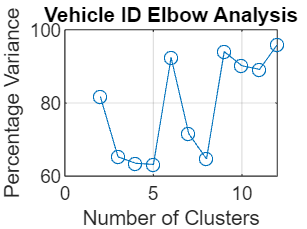

%Elbow curve vehicle id cluster
plot(k_values, variance_pct_vehicle, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Vehicle ID Elbow Analysis');
grid on;

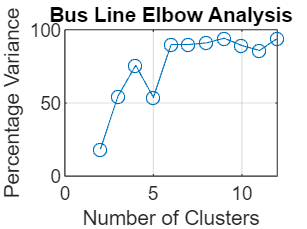

%Elbow curve bus line cluster
plot(k_values, variance_pct_busline, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Bus Line Elbow Analysis');
grid on;

% Cluster indices
idx_line = kmeans(bus_line, 5);
idx_vehicle = kmeans(vehicle_id, 6);
idx_driver = kmeans(driver_id, 5);

% Assign a new ID to each cluster
cluster_line_ids = (1:5)';
cluster_vehicle_ids = (1:6)';
cluster_driver_ids = (1:5)';

% Assign a new ID to each cluster
new_ids_line = cluster_line_ids(idx_line);
new_ids_vehicle = cluster_vehicle_ids(idx_vehicle);
new_ids_driver = cluster_driver_ids(idx_driver);

% Replace the original IDs in the dataset with the new IDs
short_matrix_no_id = [short_matrix_no_id, new_ids_line new_ids_vehicle new_ids_driver];

X = short_matrix_no_id;
%remove old ids
X(:, [1,6,8]) = [];
Y = short_matrix_no_id(:,15);

% Apply a PCA
pca_component = X(:,[1:4,6:11, 14]);
% Run PCA on numeric predictors only. Categorical predictors are passed through PCA untouched.
[pcaCoefficients, pcaScores, latent, t_sq, explained, pcaCenters] = pca(pca_component);
% Keep enough components to explain the desired amount of variance.
explainedVarianceToKeepAsFraction = 99/100;
numComponentsToKeep = find(cumsum(explained)/sum(explained) >= explainedVarianceToKeepAsFraction, 1);
numComponentsToKeep

numComponentsToKeep = 9

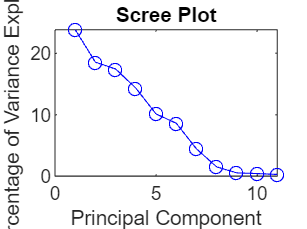

% Plot scree plot
figure;
plot(explained, 'bo-');
xlabel('Principal Component');
ylabel('Percentage of Variance Explained');
title('Scree Plot');

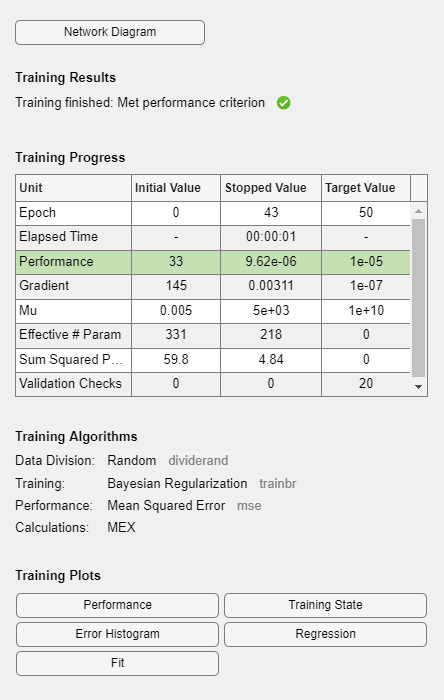


% Train neural network
avg_accuracy = 0;
avg_MSE = 0;
avg_COV = 0;
n_cycle=50;

for i = 1:n_cycle
    % Split data into training and testing sets
    train_ratio = 0.5;
    train_size = round(train_ratio*size(X,1));
    train_idx = randperm(size(X,1),train_size);
    test_idx = setdiff(1:size(X,1),train_idx);
    X_train = X(train_idx,:);
    Y_train = Y(train_idx,:);
    X_test = X(test_idx,:);
    Y_test = Y(test_idx,:);

    % Define neural network
    input_size = size(X_train,2);
    output_size = 1;
    hidden_size = 15;
    net = fitnet(hidden_size);
    net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
    net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
    net.divideParam.trainRatio = 0.5; % Training set proportion
    net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
    net.divideParam.testRatio = 0; % No testing set
    net.trainParam.max_fail = 20; % Maximum validation failures
    net.trainParam.epochs = 50; % Maximum number of epochs
    net.trainParam.goal = 1e-5; % Training goal
    net.performFcn = 'mse'; % Mean squared error performance function
    net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
        'plotregression', 'plotfit'};
    %train
    [net,tr] = train(net,X_train',Y_train');
    
    % Test neural network
    Y_pred = net(X_test');
    
    % Calculate the covariance error
    cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
    avg_COV = avg_COV + cov_error;
    
    % Calculate MSE and Accuracy
    acc = mean(abs(Y_pred-Y_test')<0.02);
    avg_accuracy = avg_accuracy + acc;
    avg_MSE = avg_MSE + mse(net,Y_pred,Y_test');
    
end

avg_accuracy = avg_accuracy/n_cycle;
avg_COV = avg_COV/n_cycle;
avg_MSE = avg_MSE/n_cycle;

%Display Accuracy, MSE and Covariance error.
disp('AVG ACCURACY: '+ avg_accuracy);

   65.9995   86.9995   71.9995   32.9995   65.9995   67.9995   67.9995   85.9995   82.9995   65.9995   67.9995   89.9995   58.9995   32.9995



disp('AVG MSE: '+ avg_MSE);

   65.0000   86.0000   71.0000   32.0000   77.0000   83.0000   69.0000   58.0000   32.0000



disp('AVG COV: '+ avg_COV);

   1.0e+04 *

    3.6214    3.6235    3.6220    3.6181    3.6216    3.6228    3.6235    3.6207    3.6181



% Display the covariance matrix
cov(Y_pred,Y_test)

ans =     5.9994    5.9998
    5.9998    6.0002
